# Example 7.1: Deterministic Decision-Making

Note: this script reproduces Example 7.1 (Section 7.1) of **Statistics for Chemical Engineers**: sizing an on-site power generator for a random (Weibull) load, using a deterministic approach. Victor Z UW-Madison, 2022 generator sizing example (deterministic solution)

clc; clear all; close all hidden;

## Load scenarios

generate scenarios for random load

rng(0)
N=1000;
X=wblrnd(10,2,N,1);

## Deterministic solution

find deterministic solution

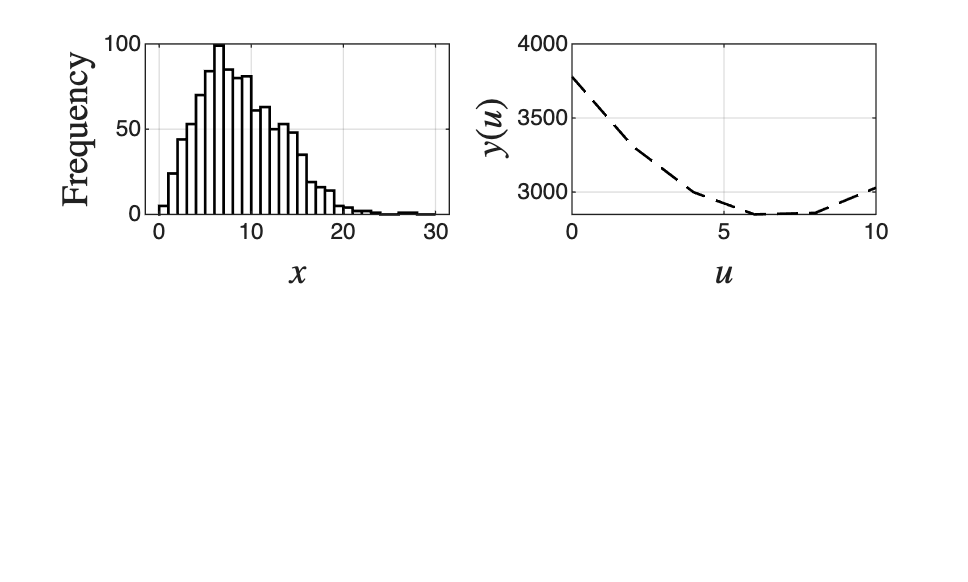

u=0:2:10;
x=max(X);

for k=1:length(u)
yd(k)=myfun(u(k),x);
end

% visualize deterministic objective against decision
figure(1)
subplot(2,2,1)
histogram(X,0:1:30,'Normalization','count','EdgeColor','black','FaceColor','white','LineWidth',1)
grid on
hold on
xlabel('$x$','Interpreter','latex','FontSize',14)
ylabel('$\textrm{Frequency}$','Interpreter','latex','FontSize',14)
subplot(2,2,2)
plot(u,yd,'LineWidth',1,'Color','black','LineStyle','--')
grid on
hold on
xlabel('$u$','Interpreter','latex','FontSize',14)
ylabel('$y(u)$','Interpreter','latex','FontSize',14)


% find optimal size that 
idx=find(yd==min(yd));
ud=u(idx);

## Deterministic solution under uncertainty

evaluate how the deterministic solution ud behaves when it confronts uncertainty

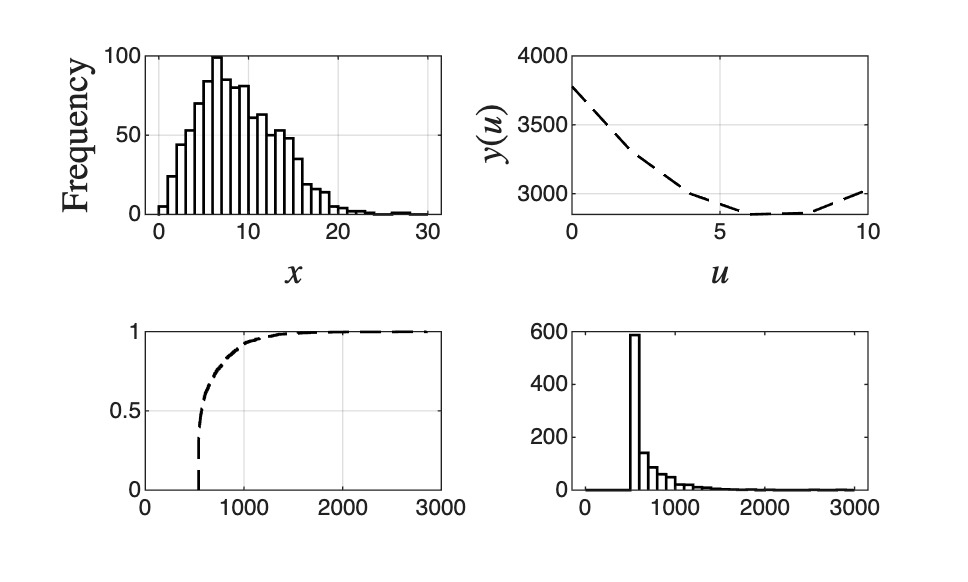

yd=myfun(ud,X);
subplot(2,2,3)
[F,t]=ecdf(yd);
stairs(t,F,'LineWidth',1,'Color','black','LineStyle','--')
grid on
hold on
subplot(2,2,4)
histogram(yd,0:100:3000,'Normalization','count','EdgeColor','black','FaceColor','white','LineWidth',1)
hold on


% mean
Ed = mean(yd)

Ed = 674.1457

## Comparison with doing nothing

compare against do nothing

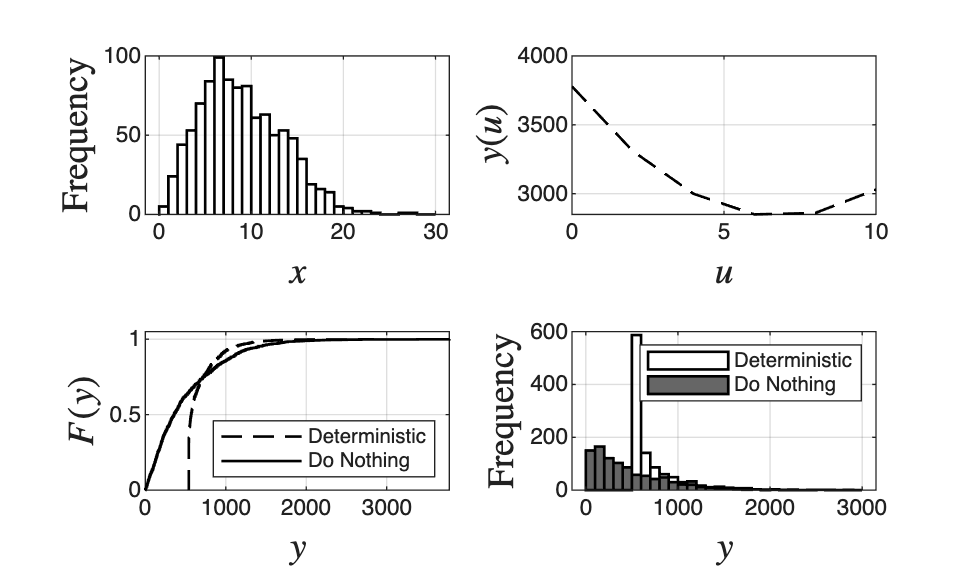

u0=0;
y0=myfun(u0,X);

subplot(2,2,3)
[F,t]=ecdf(y0);
stairs(t,F,'LineWidth',1,'Color','black','LineStyle','-')
grid on
axis([ 0 max(y0) 0 1.05])
xlabel('$y$','Interpreter','latex','FontSize',14)
ylabel('$F(y)$','Interpreter','latex','FontSize',14)
legend('Deterministic','Do Nothing','location','southeast')
subplot(2,2,4)
histogram(y0,0:100:3000,'Normalization','count','EdgeColor','black','FaceColor','black','LineWidth',1)
grid on
legend('Deterministic','Do Nothing')
xlabel('$y$','Interpreter','latex','FontSize',14)
ylabel('$\textrm{Frequency}$','Interpreter','latex','FontSize',14)
print -depsc -r1200 ch7_generator_det.eps


% mean
E0 = mean(y0)

E0 = 501.2870


 function y=myfun(u,X)
 
   R = max(X-u,0);
 y = 5*(R.^2) + 15*u.^2;
 
 end

## Note

As in the book, the deterministic decision ignores the spread of the cost: it can shave peak costs, but its performance under uncertainty must be checked against the alternatives.